# ForestFire UAV - Concept Design

## **Background:**

Heat and drought in the western United States has resulted in greater numbers and more devastating forest fires.  Fighting forest fires requires an experienced ground crew and often heavy-lift operations in an extreme environment coordinated through observations and communications.  A field-ready UAV possessing visual and sensor-based observations, communications, reactive response and lift/ballast capabilities can contribute to operational support of the fire crew and its safety.

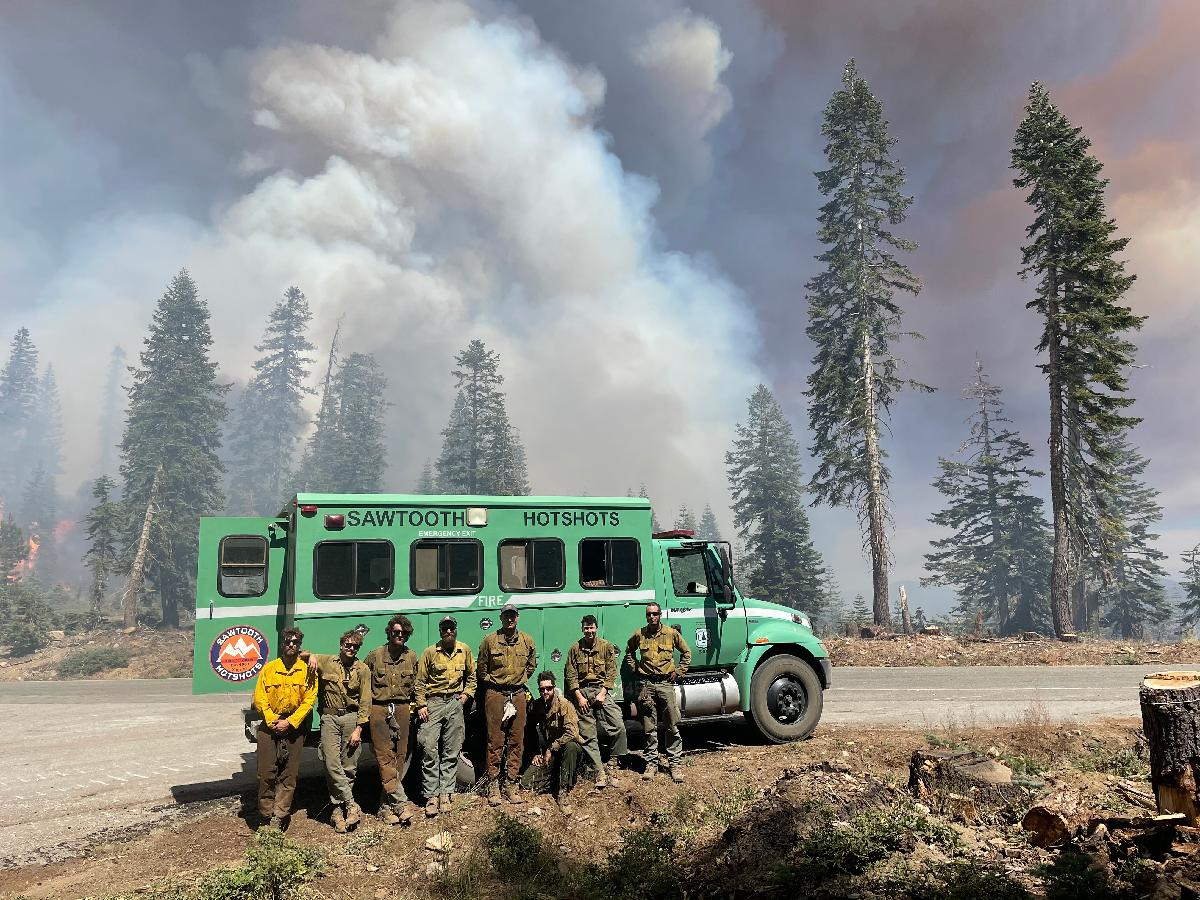

## **Project Description:**

Year 1 of the *Forest Fire UAV Platform *project is to design/develop a UAV platform (airframe, powerplant and propulsion) for a field-ready UAV developed to support crews fighting forest fires.  The UAV requires light air-lift capability, high heat, weather and damage tolerance, it must be stable in higher winds and altitudes.  The UAV platform needs to be simple, field-serviceable and travel with the crew deployed from their truck.  A test subsystem, including safe test fixtures, test cell and data acquisition, will be developed to qualify the structural airframe, powerplant and propulsion subsystems.

### Major Design Tasks:

Specifically, the *Forest Fire UAV Platform* project is to design, develop, build  and test the UAV platform.  The are four (4) major tasks in the year 1 project:

- Custom Airframe Structure Design:  Trade-off studies for concept selection between helicopters, quadcopters, hexacopters, octocopters etc . . . will be conducted.   Light-weighting of the airframe is important while "best" supporting damage tolerance, deformation, stiffness and load requirements.  Stable, light air-lift of tool, instrumentation, rescue, medical payloads is required.  Transport by truck from site-to-site by highway and rough terrain as well as field serviceability is required.

- Power Plant Design:  The primary design task for the power plant is to configure, size and select battery and/or hydrogen fuel cell subsystems, including storage.  Hybrid designs may be required.  Fast, robust field refueling/recharging is desired.

- Propulsion Subsystem Design:  Configuration and sizing of motors and propellers to maximize the hover operational mode flight time with a light air-lift payload.  Electric motors will likely be the *prime mover* selected for power and weight.  Trade-off studies for propulsion could include shrouded contra-rotating propellers.  Flight stability with payload in hot wind gusts and at higher elevation is required.

- Test Fixture/Cell Design: The design, development and fabrication of test fixtures and test cell is required to determine operational design parameters leading to qualifying the design.  Test fixtures and test cell support data acquisition for design cases such as:

- What structural loads are developed in air-lift and observation modes, how do wind gusts change structural loading?  Is the airframe damage tolerant, what is the expected life of the airframe?

- What is the power vs. time of the power plant?  How much heat is generated under load in the power plant?  Is the power output sensitive to forest fire heat?  How long can the air-lift be maintained?  What is the power budget for the platform, is power available for sensors, communications and controllers?

- Does the powertrain generate the required lift? How do the flight characteristics change vs. speed, power and weight?   How many lifting elements are needed for fault tolerance?  How stable is the platform?

- *Constrained flight* is performed in the "test cell" to **safely** conduct testing, flight qualification and demonstration.  *Constrained flight* is limited to vertical hover to demonstrate light air-lift capability and hover flight-time duration.

**Note:**  Outfitting the *Forest Fire UAV platform* with sensors for observations, communications, controls for piloted and/or autonomous free-flight is beyond the scope of the year 1 project.

### **Desired Student Skillset:**

Project skills include CAD and model-based design (MATLAB/Python) to support selection and initial design of the UAV airframe structure, power plant and propulsion subsystems.  Light-weighting will be an important element of the airframe design which includes material characterization/selection.  Interest is sensors and data acquisition for test, system integration and qualification is desired.  FEA and CFD will be used to support refined design analysis and optimization.  Drone experience is helpful even though UAV free flight is not within the scope of the year 1 project.

### **Special Considerations:**

No special requirement for student status.

## Team Leadership Responsibilities:

- Team Leader:  James Drosdick

- Aero Structure:  Roshen Arun

- Propulsion:  Jake Giacchetto

- Power:  Reda Morchid

- CAD:  Renee Van Dyke

- MATLAB Design Model:  Kieun Nam

- Testing:  Evan Grace

- Fabrication:  Livingstone Bond

## Team Member Responsibilities:

- Aero Structure:  Roshen Arun (lead), Renee Van Dyke, Livingstone Bond, Kieun Nam

- Propulsion:  Jake Giacchetto (lead), James Drosdick, Evan Grace, Reda Morchid

- Power:  Reda Morchid (lead), Kieun Nam, James Drosdick

- Test:  Evan Grace (lead),

- Fabrication:  Livingstone Bond (lead)

## Nominal Design Objectives with Payload:

- Design a UAV platform to support type 1 fire fighters of Wildland fires (Hotshots).

- Size:

-     Diameter:  $D_{UAV} = 48 \: \text{in} $

-     Height:  $h_{UAV} = 24 \: \text{in}$

-     Weight:  $Weight_{UAV} = 25 \: \text{lbf}$

- Payload:  $P_{UAV} = 25 \: \text{lbf} $ - (2.5*current)

- Range:  $R_{UAV} = 25 \: \text{miles} $ - (2.5*current)

- Loiter/Hover: $t_{Hover, Loiter} = 2 \: \text{hours} $ - (4*current)

- Cruise Speed:  $S_{Cruise} = 20 \: \text{mph}$ - (same as current)

- Rate of Climb (RoC):  $RoC = 100 \: \text{ft/min} = 0.51 \: \text{m/s}$, assume $RoD = -RoC$

- Vertical Acceleration:  $g = 0.2 \: \text{g} = 6.44 \: \text{ft/s}^{2} = 1.96 \: \text{m/s}^{2}$

- Mission Profile:

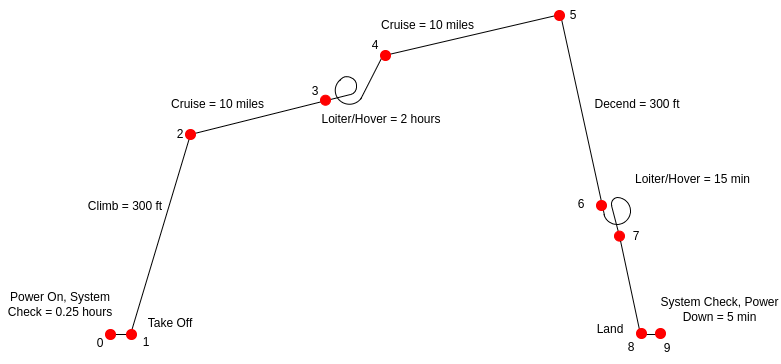

### **Wildland Fire UAV metrics:**

We will formulate the design metrics and specifications into the following form:

Minimize $f(x)$ or Maximize $f(x)$

Subject to the following constraints:

- Inequality constraints:  $g_{j}(x) \leq 0 \: \text{for} \: j = 1, 2, 3, \ldots , J$

- Equality constraints:  $h_{k}(x) = 0 \: \text{for} \: k = 1, 2, 3, \ldots,  K$

- Design parameters:  constants

- Bounds on the design variables:  $x_{i}^{lower bound} \leq x_{i} \leq x_{i}^{upper bound}$

This problem formulation is referred to as the nonlinear programming (NLP) standard form. The overall design measuring stick is the objective function: $f(x)$ 


$$\min  \left (-f(x) \right ) = \max f(x)$$



$$\max f(x)_{uav} =  f(x)_{aeroStructure} + f(x)_{power} + f(x)_{propulsion}$$


#### **aerostructure:**


$$f(x)_{aeroStructure} = \frac{1}{cost} \left(\frac{stiffness}{weight} \right )$$


- 
$$\frac{stiffness}{weight} \propto \frac{stiffness}{mass} = (\omega_{n})^2. $$
  

- $f(x)_{aeroStructure} = \frac{1}{cost_{AeroStructure}} \sum \left( \omega_{n} \right )$; natural frequencies for relevant modes.

**Power Subsytem:**


$$f(x)_{power} = \frac{1}{cost_{power}} \frac{energy \: density}{weight} $$


**Propulsion Subsystem:**


$$f(x)_{propulsion} = \frac{1}{cost_{propulsion}} \left(\frac{thrust}{weight} \right)$$


In the above subsystem objective functions, the **cost is an estimate of $$**.

These functions should be normalized and weighted by a “reliability” metric.

## Design Specs:

- Payload:  25 lbf

- Range: 20 miles

- Hover:  2 hrs

- Transport by truck or trailer

-     Interstate, Highway and All-Terrrain 

-     top of the truck:  6' wide x 8' long

- Fault Tolerant:  Must stay in the air after loss of 1 motor/prop

- In-Service Maintenance:  30-45 min after return to camp.

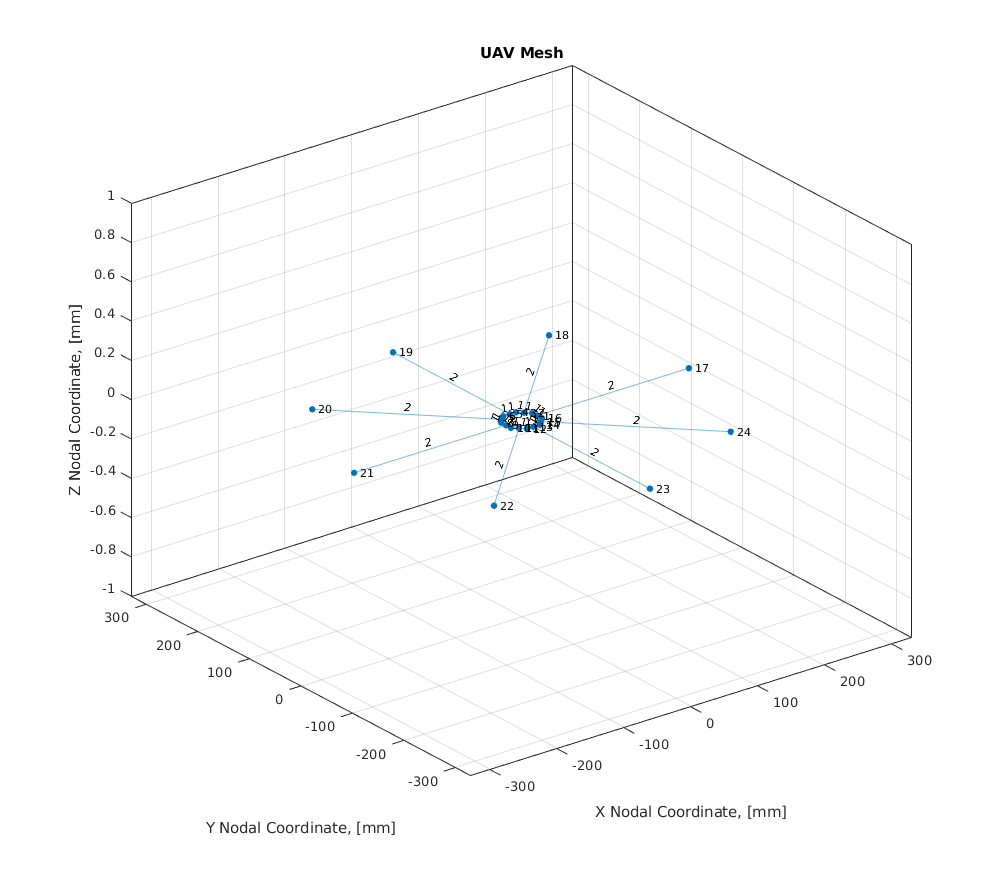

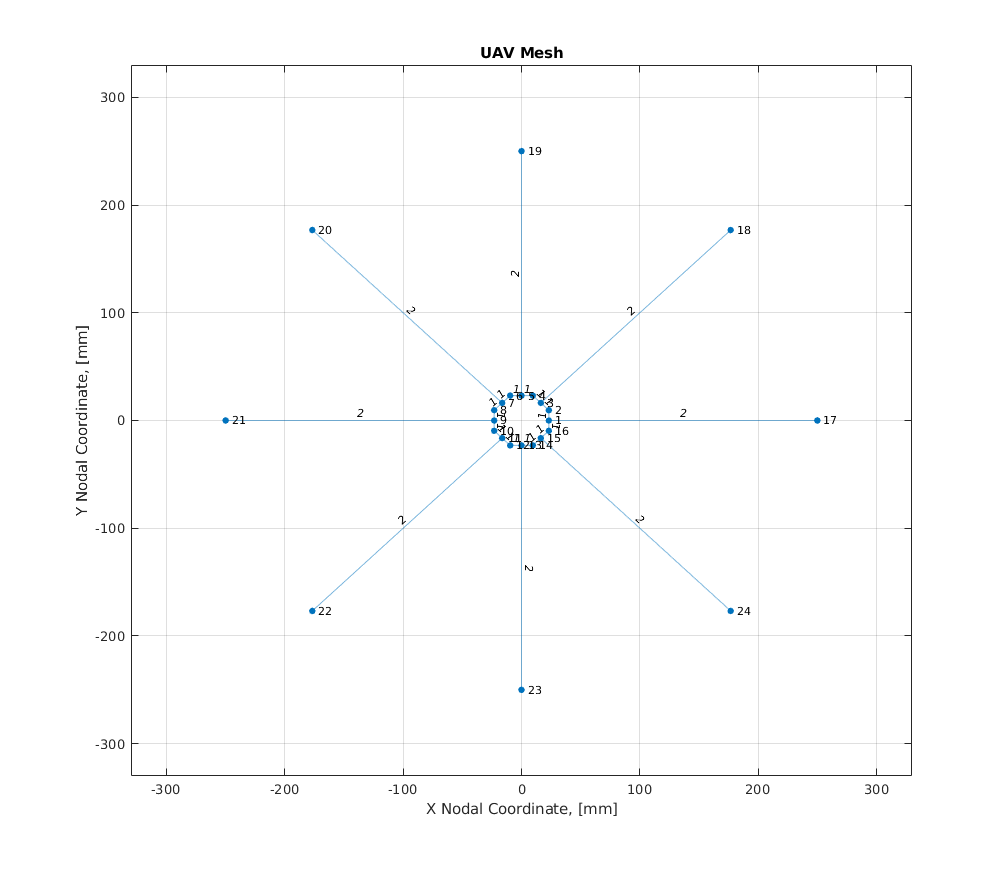

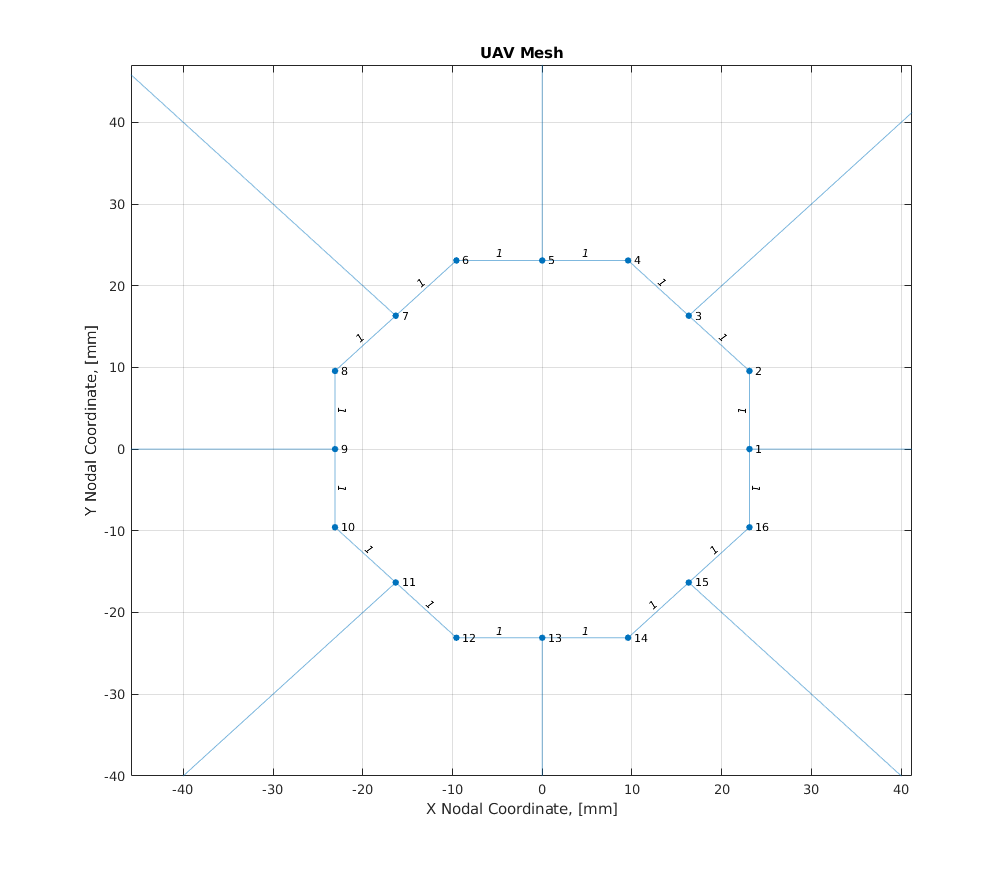

## Design Notes:

### UAV Aerostructure Subsystem Design:

Drones can be fixed-wing (maximum range), multicopter (short range), or hybrid (mixed missions with VTOL capability).  Their maximum take-off weight (MTOW) and dynamic requirements determine their total thrust [N]. Drones generally require a maximum thrust capacity which is 2.5 times the MTOW.

- performance metric:  stiffness-to-weight ratio:  natural frequency; see above

- cost normalized performance metric:  stiffness-to-weight ratio/cost

#### aerostructure design variables:

- mission profile(s)

- size, nominal dimensions:

-     UAV:  nominal diameter, height

-     Hub: diameter, height

-     Payload: diameter, height

-     Arm section and material properties.

- configuration, number of arms/props: **nArms**

- maximum take-off weight:  **MTOW**

#### materials:

**Aluminum**:

With its lightweight properties and high strength-to-weight ratio,  aluminum has been the preferred choice of metal materials for aerospace  applications. Additional benefits that aluminum offers for aircraft  applications include:

- Durability in high stressed environments, temperature and pressure extremes,

- Formability allows for easy fabrication for smaller aircraft parts,

- Aluminum alloys offer high electrical and thermal conductivity,

- Due to the lightweight properties of aluminum, it offers a  cost-effective alternative to other material types.

**Aluminum Grade:  Aluminum Grade Properties**

- **Alloy 2014:  **Ideal for framework due to its machinability and strength. Does  not provide corrosion-resistance when compared to other aluminum grades. It is not well-suited for applications with high environmental  stressors or corrosive environments.

- **Alloy 2024:  **Widely used among aircraft and aerospace components. Provides  stress resistance, high-tensile strength, and can be heat treated.  Aluminum sheet and plate are ideal for applications such as aircraft  wings, structures, or repair purposes.  **Should NOT be welded.**

- **Alloy 3003:  **Provides corrosion-resistance and weldability. It is one of the  more commonly used aluminum alloys for aviation and aircraft. Alloy 3003 is not heat-treatable.

- [**Alloy 5052**](https://www.industrialmetalsupply.com/shop-metal/5052)**:  **Another non-heat treatable aluminum alloy, alloy 5052 offers a  high fatigue strength when compared to other aluminum grades. It offers  good corrosion-resistance and formability properties. It is commonly used for aircraft fuel tanks.

- [**Alloy 6061**](https://www.industrialmetalsupply.com/shop-metal/6061)**:  **Workable with excellent corrosion-resistance, alloy 6061 can be welded and brazed. It is commonly used for wings or fuselage.

- [**Alloy 6063**](https://www.industrialmetalsupply.com/shop-metal/6063)**:  **Ideal for anodizing applications or architectural structures.  Alloy 6063 offers high-tensile properties with high  corrosion-resistance. Often used for aesthetic purposes and finishes.

- **Alloy 7050:  **Ideal for wing skins and military aircraft, alloy 7050 has an excellent strength-to-weight ratio and can be heat-treated.  **Should NOT be welded.**

- **Alloy 7068:  **Commonly used for aircraft applications, alloy 7068 is one of the strongest aluminum alloys available for aerospace applications. Its  corrosion-resistance and high-strength make it a popular aluminum alloy grade for applications that are subjected to high environmental  stressors.

- **Alloy 7075:  **Aluminum alloy 7075 offers high fatigue-resistance and average corrosion-resistance. It has high levels of zinc making it comparable in strength to steel. It is ideal for high-stressed components like gears  or fuselages. One of the most common aluminum alloys used for aerospace  components.

- **Alloy 7475:**  Developed by the Alcoa, Aluminum Alloy 7475 is most often used in high performance aerospace applications that require high resistance to fracture.  Providing uncompromising strength and crack fatigue resistance, Alloy 7475 offers the industry’s best fracture toughness. It can also be readily formed and machined in the annealed condition, with improved forming available by heating the alloy to 250°F.  It has been frequently used for components such as wing spars, wing skins, and  fuselage bulkheads.  **Should NOT be welded.**

**Composites:**

- local doublers

- Prefabricated composite Sections:

-     clear water composites: https://www.clearwatercomposites.com/products/carbon-fiber-tubes/octagonal/

-     rockwest composites: https://www.rockwestcomposites.com/tubing/shaped-tubing/octagonal-tubing

-     dragonplate composites: https://dragonplate.com/carbon-fiber-tubes

### Propulsion Subsystem Design:

The propulsion subsystem is made up of the motor, propellar and electronic speed control, (ESC).

- performance metric:  thrust-to-weight ratio:  T/W

- cost normalized performance metric:  thrust-to-weight ratio/cost

#### motor design variables:

The nominal and maximum thrust determines the required motor speed and torque.  Motor and winding size are selected to achieve optimal power, dimensions, weight, battery voltage and current, as well as an efficient and operational service life.  Mechanical strength requirements are determined by the aerodynamic and gyroscopic forces as well as the required operational service life.

- thrust,

- diameter,

- height,

- weight,

#### Propeller Design Variables:

Dimensional and aerodynamic requirements determine the number of propellers and their characteristics. Propellers can provide lift and thrust, but they also generate drag during linear flight. VTOL drone designs often need the lift-generating propellers to be locked at a given angle to limit drag during flight in aircraft mode. The efficiency of a propulsion system is defined by the thrust provided by the power supplied.

- thrust,

- diameter,

- pitch,

- performance

#### Maxon Motors Paired with Mejzlik Propellers:

- EC 69 Flat UAV:  brushless, up to 8.4kg thrust, 18.5 lbf

-     diameter: $d_{motor} = 69 \: \text{mm} = 2.72 \: \text{in}$, 

-     Height:  $h_{motor} = 30 \: \text{mm} = 1.18 \: \text{in}$

-     Weight of motor including cables:  $W_{Motor} = 269 \: {g} = 0.6 \: \text{lbf}$

- Props:

-     Mejzlik Propeller 20x6.7

-         Diameter: $d_{Prop} = 20 \: \text{in} = 508 \: \text{mm}$

-         Pitch: $p_{Prop} = 6.7 \: \text{in} = 170.2 \: \text{mm}$

-         Weight of Propeller:  $W_{Prop} = 30 \: \text{g} = 0.07 \: \text{lbf}$

-         Max. speed:  $n_{max} = 9000 \: \text{rpm}$

-         Material:  carbon fiber, glass fiber, roving, polyurethane, epoxy

-     Mejzlik Propeller 22x7.4

-         Diameter: $d_{Prop} = 22 \: \text{in} = 558.8 \: \text{mm}$

-         Pitch: $p_{Prop} = 7.4 \: \text{in} = 188.0 \: \text{mm}$

-         Weight of Propeller:  $W_{Prop} = 44 \: \text{g} = 0.1 \: \text{lbf}$

-         Max. speed:  $n_{max} = 8200 \: \text{rpm}$

-         Material:  carbon fiber, glass fiber, roving, polyurethane, epoxy

-     Mejzlik Propeller 24x8.1

-         Diameter: $d_{Prop} = 24 \: \text{in} = 0.94 \: \text{mm}$

-         Pitch: $p_{Prop} = 8.1\: \text{in} = 0.32 \: \text{mm}$

-         Weight of Propeller:  $W_{Prop} = 55 \: \text{g} = 0.12 \: \text{lbf}$

-         Max. speed:  $n_{max} = 7500 \: \text{rpm}$

-         Material:  carbon fiber, glass fiber, roving, polyurethane, epoxy

- EC 87 Flat UAV:  brushless, up to 9kg thrust, 20 lbf

-     diameter: $d_{motor} = 87 \: \text{mm} = 3.43 \: \text{in}$, 

-     Height:  $h_{motor} = 30 \: \text{mm} = 1.18 \: \text{in}$

-     Weight of motor including cables:  $W_{Motor} = 269 \: {g} = 0.6 \: \text{lbf}$

- Props:

-     Mejzlik Propeller 26x8.7

-         Diameter: $d_{Prop} = 26 \: \text{in} = 660.4 \: \text{mm}$

-         Pitch: $p_{Prop} = 8.7 \: \text{in} = 223.0 \: \text{mm}$

-         Weight of Propeller:  $W_{Prop} = 66 \: \text{g} = 0.15 \: \text{lbf}$

-         Max. speed:  $n_{max} = 6900 \: \text{rpm}$

-         Material:  carbon fiber, glass fiber, roving, polyurethane, epoxy

-     Mejzlik Propeller 28x9.4

-         Diameter: $d_{Prop} = 28 \: \text{in} = 711.2 \: \text{mm}$

-         Pitch: $p_{Prop} = 9.4 \: \text{in} = 238.8 \: \text{mm}$

-         Weight of Propeller:  $W_{Prop} = 76 \: \text{g} = 0.17 \: \text{lbf}$

-         Max. speed:  $n_{max} = 6400 \: \text{rpm}$

-         Material:  carbon fiber, glass fiber, roving, polyurethane, epoxy

-     Mejzlik Propeller 30x10.0

-         Diameter: $d_{Prop} = 30 \: \text{in} = 762.0 \: \text{mm}$

-         Pitch: $p_{Prop} = 10.0\: \text{in} = 254.0 \: \text{mm}$

-         Weight of Propeller:  $W_{Prop} = 71 \: \text{g} = 0.16 \: \text{lbf}$

-         Max. speed:  $n_{max} = 6000 \: \text{rpm}$

-         Material:  carbon fiber, glass fiber, roving, polyurethane, epoxy

    Additional notes:

- larger the propellar the greater the lifting

- 30" diameter rotors

- 36" rotor $200

- 2" of clearance between rotors

- efficiency 2-rotor system, contra-rotating

-     Tmotor:  [https://store.tmotor.com/](https://store.tmotor.com/)

-     Xoar:  [https://www.xoarintl.com/rc-propellers/](https://www.xoarintl.com/rc-propellers/)

-     Mejzlik:  [https://www.mejzlik.eu/technical-data](https://www.mejzlik.eu/technical-data)

### Power Subsystem Design:

#### Batteries:

Most drone manufacturers use lithium-polymer batteries rather than lithium-ion batteries due to higher discharge rates (higher discharge current).

- performance metric:  Energy Density = Energy per volume

- cost normalized performance metric:  Energy Density/cost

#### Battery Design Variables:

- Energy  [Wh]

- Capacity [mAh]

- Size:  LxWxH

- Weight [g]

- Nom. voltage [V]

- Min. voltage [V]

- C rating [xC]

Tattu-Pro 22000mAh 44.4V 25C 12S1P Lipo Smart Battery Pack with AS150U-F Plug

- Model:  TAPRAS22K1225X

- Energy:  $E = 976.8 \: \text{Wh}$

- Capacity:  $Cap = 22000 \: \text{mAh}$

- Nominal Voltage:  $V_{nom} = 44.4 \: \text{V}$

- Recommended Landing Voltage/Min Voltage:  $V_{min} = 43.2\: \text{V}$

- Weight:  $W = 6400 g =6.4 \: \text{kg} = 14.1 \: \text{lbf}$

- Size: $LxWxH = 238 x 174 x 117 \: \text{mm} = 9.37x6.85x4.6 \: \text{in}$

### ESCs:

The ESC controls the motor based on values determined by the flight computer, and is powered by the battery. The control interfaces used are PWM, multi-shot, and UAV CAN (CAN bus systems).

Good air convection at the ESC improves the nominal power. The ESC regulation must be configured by maxon taking into account various variables, such as the propeller’s inertia, acceleration/decceleration, and more for highest possible efficiency.

- heat 6s, 8s, 12s

- thrust at 20% throttle

- limited the head room on the 70% of max throttle at hover thrust

- power efficiency

- 12S batteries

- UAV-ESC 52/30 Data

-     Electronic speed controller designed for professional UAV applications

-     Size:  Dimensions LxWxH = 86x38x17 mm = 3.39x1.5x0.67

-     Weight, including cable, including housing:  207 g

### Controller:

The drone’s flight computer is the main control system for flight control, gyroscopic measurement, communications, payload control, etc. Most flight computers are based on open-source hardware and software (e.g. PX4).

- DJI S1000 system 

## **References:**

- Raymer, D. P., Aircraft Design: A Conceptual Approach:  

- Practical reliability Engineering Book:  VT Online:  [https://onlinelibrary-wiley-com.ezproxy.lib.vt.edu/doi/book/10.1002/9781119961260](https://onlinelibrary-wiley-com.ezproxy.lib.vt.edu/doi/book/10.1002/9781119961260)

## Initialize MATLAB workspace

clear all;                                      % initialize MATLAB workspace
format short e;                                 % default output format

## Power Subsystem

### Design Variables:

- Energy  [Wh]

- Capacity [mAh]

- Size:  LxWxH

- Weight [g]

- Nom. voltage [V]

- Min. voltage [V]

- C rating [xC]

Tattu Pro 22000mAh 44.4V 25C 12S1P Lipo Smart Battery Pack with AS150U-F Plug

- Model:  TAPRAS22K1225X

- Energy:  $E = 976.8 \: \text{Wh}$

- Capacity:  $Cap = 22000 \: \text{mAh}$

- Nominal Voltage:  $V_{nom} = 44.4 \: \text{V}$

- Recommended Landing Voltage/Min Voltage:  $V_{min} = 43.2\: \text{V}$

- Weight:  $W = 6400 g =6.4 \: \text{kg} = 14.1 \: \text{lbf}$

- Size: $LxWxH = 238 x 174 x 117 \: \text{mm} = 9.37x6.85x4.6 \: \text{in}$

power = power_Subsystem('TAPRAS22K1225X');   % power subsystem TATTU-Pro battery

## Hub Design

### Section Properties:  Rectangular Structural tubing:

- h = 40 mm,

- b = 12 mm,

- wall thickness = 3 mm

h = 40;                                         % hub section height [mm]
b = 12;                                         % hub section width [mm]
t = 3;                                          % hub wall thickness [mm]
hub.sectn = sectn_rectangularTube(h, b, t);     % hub section properties
hub.matrl = matrl_aluminum6061_T6('MPa');       % hub material properties

## Arm Design

### Section Properties:  Octagonal/Round Structural tubing:

- OD = 20 mm,

- wall thickness = 3 mm

OD = 20;                                        % arm OD [mm]
t = 3;                                          % arm wall thickness [mm]
arm.sectn = sectn_hexagonalTube(OD, t);         % arm section properties
arm.matrl = matrl_aluminum7075_T6('MPa');       % arm material properties

## UAV Geometry

- nArms = number of arms; 3-12

- dNom = nominal diameter, diameter for circle of motors

- dHub  = diameter of hub housing determined by battery size and orientation,

- lHub  = length of hub, *incomplete*

- dPayload = diameter of payload housing, *incomplete*

- lPayload = length of payload housing, *incomplete*

### Nodal Coordinates

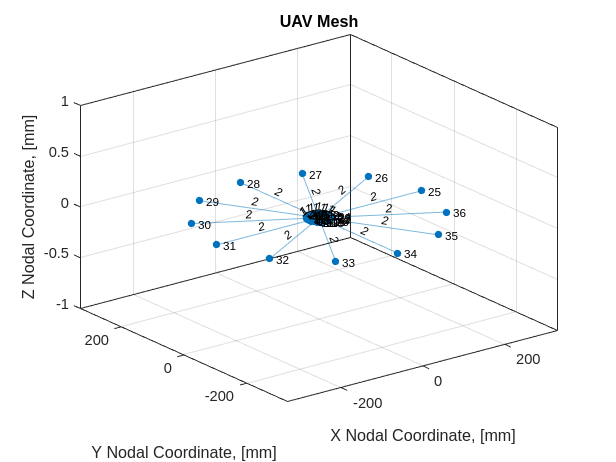

uav.nArms = 12;                                 % uav number of arms
uav.dNom = 500;                                 % uav nominal diameter [mm]
uav.dHub = 50;                                  % uav hub diameter [mm]
uav.power = power;                              % uav power data structure
uav.hub   = hub;                                % uav hub data structure
uav.arm   = arm;                                % uav arm data structure
uav=uav_geometry(uav);                          % uav geometry

% uav=uavPlot(uav);                               % uav plot

cell for prototyping functions prior to standalone functions

UAV geometry function

function [uav]=uav_geometry(uav)
    nArms = uav.nArms;                          % uav # of arms    
    dNom = uav.dNom;                            % uav nominal diameter
    rNom = dNom/2.0;                            % uav nominal radius
    dHubOut = uav.dHub;                         % uav hub diameter
    rHubOut = dHubOut/2.0;                      % uav hub radius
    nVertices = nArms;                          % hub # of vertices
    theta = 360.0/nArms;                        % hub angular layout
    %  define vertices on outside diameter of hub (corners)
    alpha0 = theta/2.0;                         % hub outside angular layout offset
    alpha = linspace(alpha0,360-alpha0,nVertices);  % hub angles for outside vertices
    NiOut = linspace(1,nVertices,nVertices);    % hub Ni at the outside vertices
    xNiOut = rHubOut*cosd(alpha);               % hub corner Ni x-coord
    yNiOut = rHubOut*sind(alpha);            % hub corner Ni y-coord
    % define vertices on inside diameter of hub (faces)
    beta0 = 0.0;                                % hub inside angular layout offset
    beta = linspace(beta0,360-theta,nVertices); % hub angles for outside vertices
    NiIn = linspace(nVertices+1,2*nVertices,nVertices); % hub Ni at the inside vertices
    dxHubIn = (xNiOut(nVertices)+xNiOut(1))/2.0; % hub inside x-coord
    dyHubIn = (yNiOut(nVertices)+yNiOut(1))/2.0; % hub inside y-coord
    rHubIn = sqrt(dxHubIn^2 + dyHubIn^2);       % hub inside radius
    dHubIn = 2.0*rHubIn;                        % hub inside diameter; width across the flats
    xNiIn = rHubIn*cosd(beta);                  % hub inside Ni x-coord
    yNiIn = rHubIn*sind(beta);                  % hub inside Ni y-coord
    % generate nodes for hub
    nNodes = 0;                                 % initialize hub # of nodes
    for Ni=1:nVertices
        nNodes = nNodes+1;                      % increment # of nodes
        xNi(:,nNodes) = [xNiIn(Ni); yNiIn(Ni)]; % hub face node
        nNodes = nNodes+1;                      % increment # of nodes
        xNi(:,nNodes) = [xNiOut(Ni); yNiOut(Ni)];% hub vertex node
    end
    % generate hub elements
    nElements = 0;                              % initialize hub # of elements
%     nPlot = 0;
    for Ni = 2:nNodes
        nElements = nElements+1;                % increment # of elements
        EiNi(:,nElements) = [ Ni-1; Ni];        % Ei node list
        xEi(:,nElements) = [xNi(1,Ni-1); xNi(2,Ni-1); xNi(1,Ni); xNi(2,Ni)]; % Ni  coordinates
        % need to add arm section properties and materials
%         EiSi(nElements).sectn = hub.sectn;
%         EiMi(nElements).matrl = hub.matrl;
    end
    nElements = nElements+1;                % increment # of elements
    EiNi(:,nElements) = [nNodes; 1];        % Ei node list
    xEi(:,nElements) = [xNi(1,nNodes); xNi(2,nNodes); xNi(1,1); xNi(2,1)]; % Ni  coordinates
    % generate nodes for arms
    xNiArm = rNom*cosd(beta);                   % hub inside Ni x-coord
    yNiArm = rNom*sind(beta);                   % hub inside Ni y-coord
    for Ni=1:nArms
        nNodes = nNodes+1;                      % increment # of nodes
        xNi(:,nNodes) = [xNiArm(Ni); yNiArm(Ni)];% hub vertex node
    end
    for Ei=1:nArms
        nElements = nElements+1;                % increment # of elements
        N1 = (Ei-1)+Ei;
        N2 = 2*nArms+Ei;
        EiNi(:,nElements) = [N1; N2]; % Ei node list
        xEi(:,nElements) = [xNi(1,N1); xNi(2,N1); xNi(1,N2); xNi(2,N2)]; % Ni  coordinates
        % need to add arm section properties and materials
%         EiSi(nElements).sectn = arm.sectn;
%         EiMi(nElements).matrl = arm.matrl;
    end
    % Add hub center Node
%     nNodes = nNodes+1;                      % increment # of nodes
%     xNi(:,nNodes) = [0.0; 0.0];             % hub face node
    % add data structures to uav struct
    uav.xNI = xNi;                              % uav nodal coordinates
    uav.EiNi = EiNi;                            % uav element node vector
    uav.xEi  = xEi;                             % uav element nodal coordinates
    % MATLAB graph structure used for plotting; need to finsh plot function
    % add structural section properties as graph weights
    Sectn(1:2*nArms) = ones(1,2*nArms);         % section properties for hub
    Sectn(2*nArms+1:3*nArms) = 2*ones(1,nArms); % sectioon properties for arms
    uavGraph = graph(EiNi(1,:),EiNi(2,:),Sectn);
    zp = zeros(1,length(xNi(1,:)));
    plot(uavGraph,'XData',xNi(1,:),'YData',xNi(2,:),'ZData', zp, 'EdgeLabel',uavGraph.Edges.Weight)
    title('UAV Mesh');
    xlabel('X Nodal Coordinate, [mm]');
    ylabel('Y Nodal Coordinate, [mm]');
    zlabel('Z Nodal Coordinate, [mm]');
    grid;
end

% function [hub] = hubSpokes(hub)
%     dTheta = 360.0/hub.nArms;              % hub angular layout
%     theta = linspace(0.0, 360-dTheta, hub.nArms);
% end

% function [uav] = uavPlot(uav)
%     % MATLAB graph structure used for plotting
%     % add structural section properties as graph weights
%     nArms = uav.nArms;                          % # of arms
%     Sectn(1:2*nArms) = ones(1,2*nArms);         % section properties for hub
%     Sectn(2*nArms+1:3*nArms) = 2*ones(1,nArms); % sectioon properties for arms
%     uavGraph = graph(EiNi(1,:),EiNi(2,:),Sectn);
%     zp = zeros(1,length(xNi(1,:)));
%     plot(uavGraph,'XData',xNi(1,:),'YData',xNi(2,:),'ZData', zp, 'EdgeLabel',uavGraph.Edges.Weight)
%     title('UAV Mesh');
%     xlabel('X Nodal Coordinate, [mm]');
%     ylabel('Y Nodal Coordinate, [mm]');
%     zlabel('Z Nodal Coordinate, [mm]');
%     grid;
% end